# Crack Problem

Crack solves the Poisson equation $-\Delta u =f$ in $\Omega$ and $u = g_D$ on $\partial \Omega$ in a crack domain $\Omega=\{|x|+|y|<1\}\setminus \{0 \leq x \leq 1, y=0\}$ using adaptive finite element method (AFEM). We choose f=1 and g_D such that the exact solution is $u = r^{\beta}\sin(\beta\theta)-0.25r^2,  \beta = 1/2$ in the polar coordinate.

See also Lshape, Kellogg

Copyright (C) Long Chen. See COPYRIGHT.txt for details.

close all; clear variables;

## Parameters

maxN = 4e3;     theta = 0.5;    maxIt = 50; 
N = zeros(maxIt,1);     
errL2 = zeros(maxIt,1);     
errH1 = zeros(maxIt,1);
erreta = zeros(maxIt,1);

## Generate an initial mesh

%%  Generate an initial mesh
node = [1,0; 0,1; -1,0; 0,-1; 0,0; 1,0];        % nodes
elem = [5,1,2; 5,2,3; 5,3,4; 5,4,6];            % elements
elem = label(node,elem);                        % label the mesh
bdFlag = setboundary(node,elem,'Dirichlet');    % Dirichlet boundary condition
showmesh(node,elem);                            % plot mesh

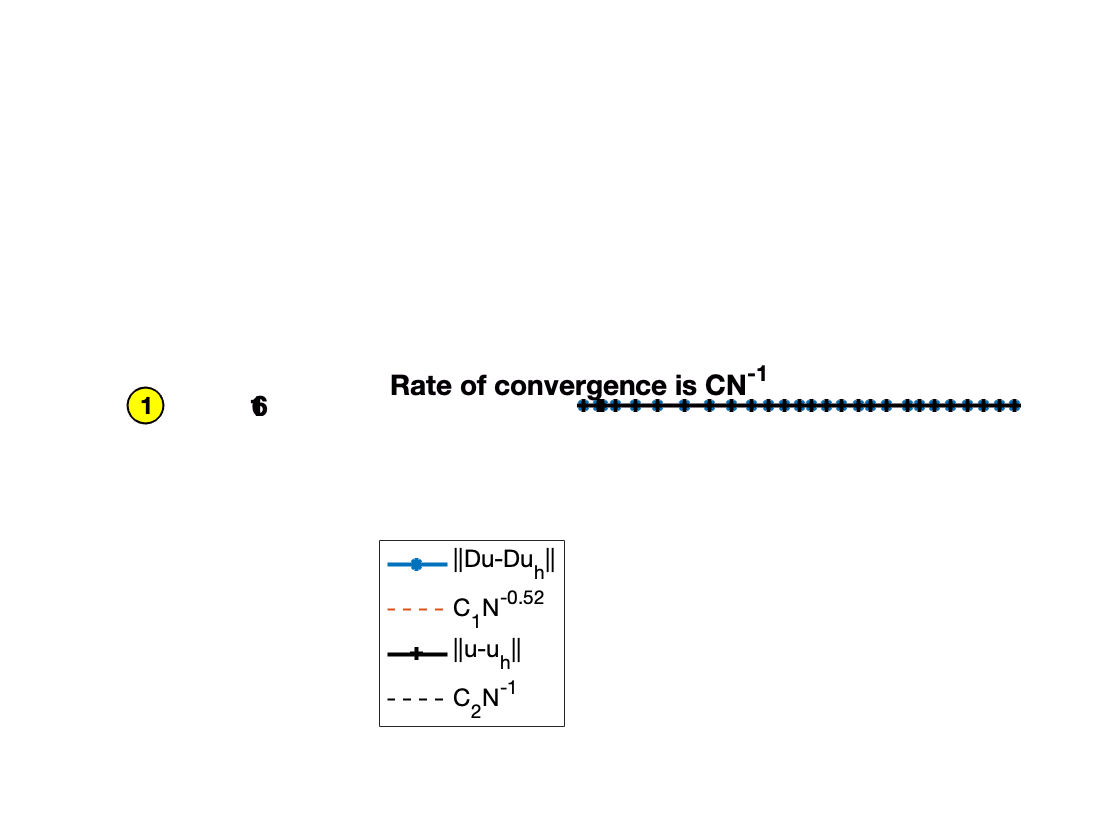

findelem(node,elem);                            % plot element indices
findnode(node,1:5);                             % plot node indices
findedge(node,[1 5; 5 6],1, 'draw');            % plot the crack edge
text(node(6,1)+0.05,node(6,2)+0.075,int2str(6), ...
     'FontSize',14,'FontWeight','bold');

Note that node 1 and node 6 are the same point (1,0)

## Get a fine mesh by uniform bisection

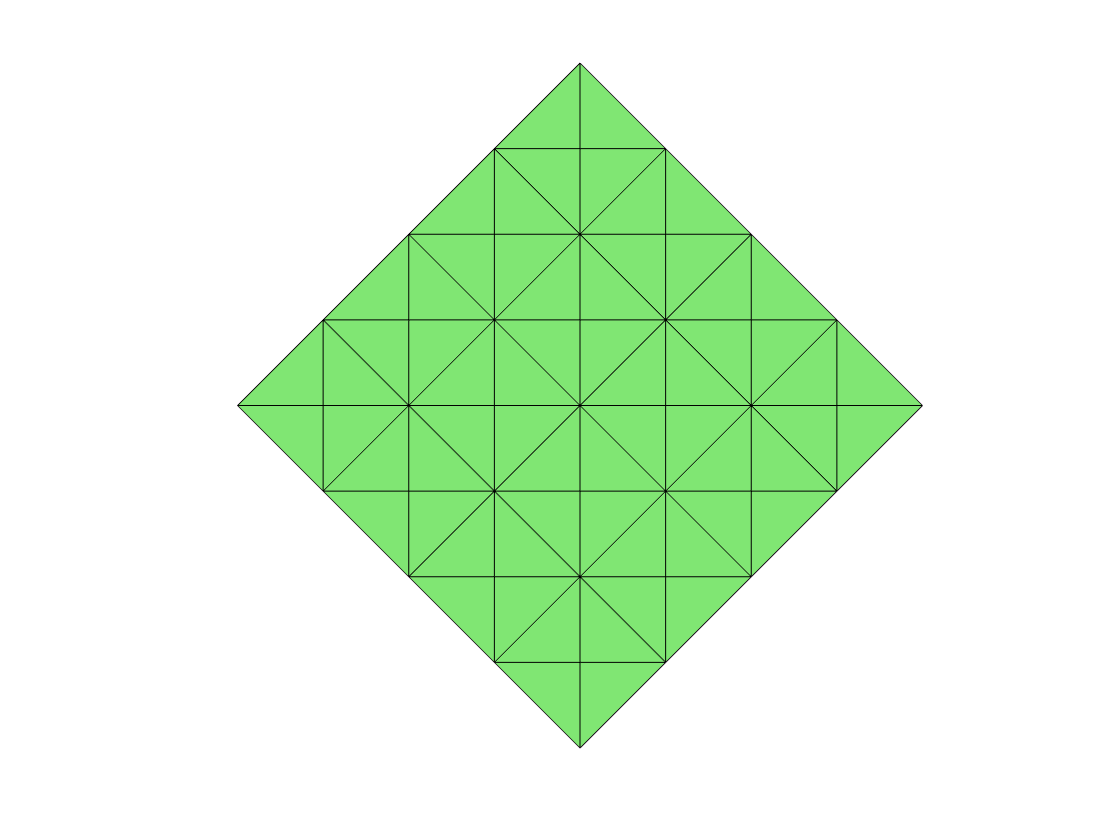

for k = 1:2
    [node,elem,bdFlag] = uniformbisect(node,elem,bdFlag);
end
clf; showmesh(node,elem);

## Set up PDE data

pde = crackdata;

## Adaptive Finite Element Method

**SOLVE** -> **ESTIMATE** -> **MARK** -> **REFINE/COARSEN**

Multigrid V-cycle Preconditioner with Conjugate Gradient Method
#dof:     2041,  #nnz:    10611, smoothing: (1,1), iter:  7,   err = 2.92e-09,   time = 0.06 s


Multigrid V-cycle Preconditioner with Conjugate Gradient Method
#dof:     2430,  #nnz:    12523, smoothing: (1,1), iter:  7,   err = 2.93e-09,   time =  0.1 s


Multigrid V-cycle Preconditioner with Conjugate Gradient Method
#dof:     2890,  #nnz:    15081, smoothing: (1,1), iter:  7,   err = 2.52e-09,   time = 0.23 s


Multigrid V-cycle Preconditioner with Conjugate Gradient Method
#dof:     3447,  #nnz:    17987, smoothing: (1,1), iter:  7,   err = 2.78e-09,   time = 0.18 s


Multigrid V-cycle Preconditioner with Conjugate Gradient Method
#dof:     4041,  #nnz:    21405, smoothing: (1,1), iter:  7,   err = 2.87e-09,   time = 0.15 s


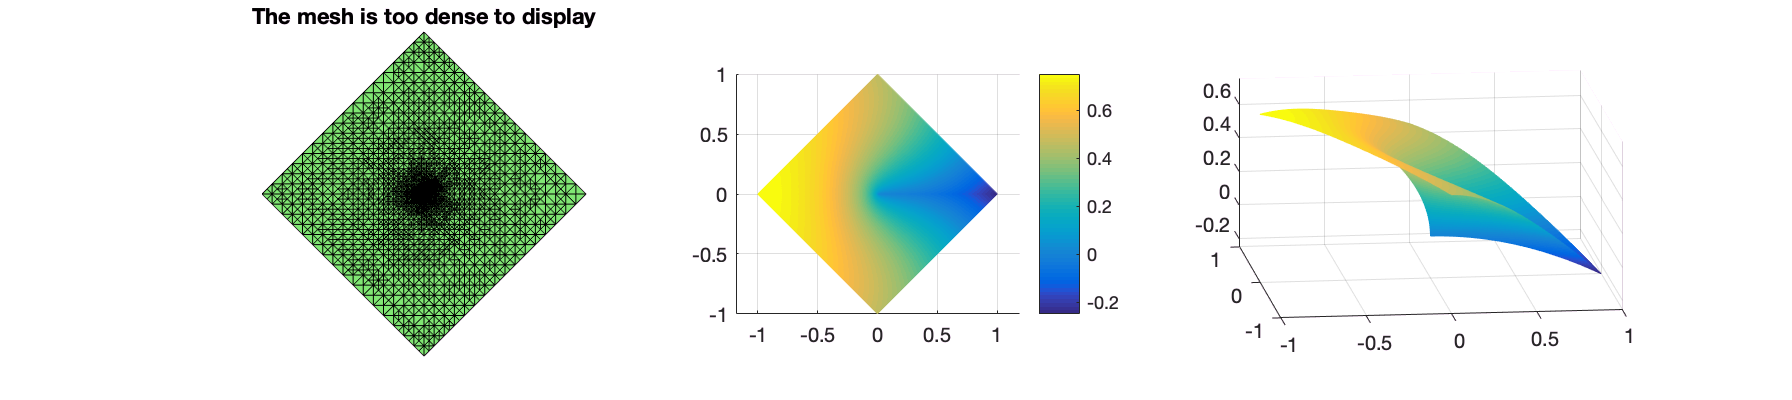

for k = 1:maxIt
    % Step 1: SOLVE
    u = Poisson(node,elem,bdFlag,pde);
    % Plot mesh and solution
    figure(1);  showresult(node,elem,u,[-7,12]);    
    % Step 2: ESTIMATE
    %eta = estimaterecovery(node,elem,u);            % recovery type
    eta = estimateresidual(node,elem,u,pde);    % residual type
    % Record error and number of vertices
    errL2(k) = getL2error(node,elem,pde.exactu,u);
    errH1(k) = getH1error(node,elem,pde.Du,u);
    erreta(k) = sqrt(sum(eta.^2));
    N(k) = size(node,1);
    if (N(k)>maxN), break; end        
    % Step 3: MARK
    markedElem = mark(elem,eta,theta);
    % Step 4: REFINE
    [node,elem,bdFlag,HB,tree] = bisect(node,elem,markedElem,bdFlag);
    % COARSEN
    eta = eleminterpolate(eta,tree);
    markedElem = mark(elem,eta,0.5*theta,'COARSEN');
    [node,elem,bdFlag] = coarsen(node,elem,markedElem,bdFlag);
end

## Plot convergence rates

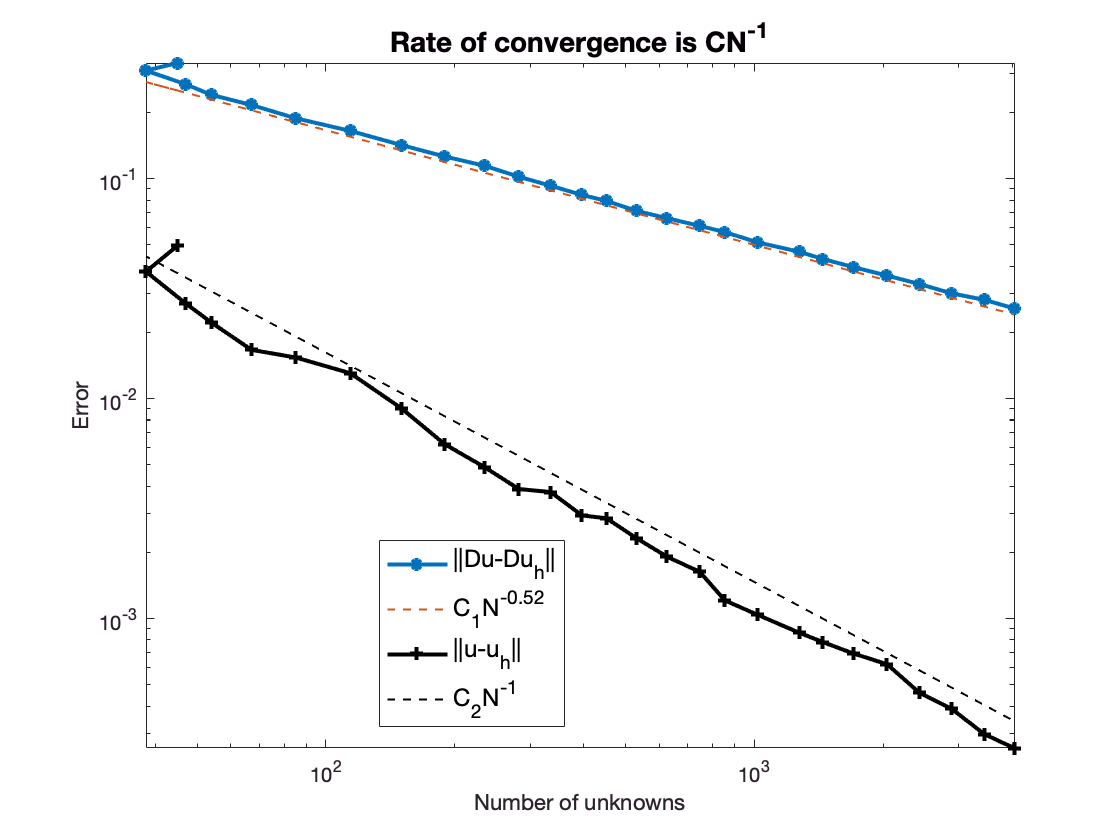

figure;
showrate2(N(1:k),errH1(1:k),5,'-*','||Du-Du_h||',...
          N(1:k),errL2(1:k),5,'k-+','||u-u_h||');

Using AFEM, we obtain optimal rate of convergence the error in the energy norm ($N^{-0.5}$) and in the $L^2$ norm ($N^{-1}$).